# Estructuras de selección o condicionales

## Estructura `if/else/elseif`

### Ejercicio 1

El discriminante de una ecuación cuadrática es


$$D=b^2 -4\textrm{ac}$$


Cuando el discriminante es positivo, la ecuación cuadrática tiene 2 raíces reales, pero cuando el discriminante es cero la ecuación cuadrática tiene una única raíz real. Por otra parte, cuando el discriminante es negativo la ecuación cuadrática no tiene raíces reales.

Solicitar al usuario por teclado que ingrese los valores de $a$, $b$ y $c$, y mostrarle por pantalla el discriminante y lo que significa. También desplegar por pantalla las raíces reales, siempre y cuando la ecuación cuadrática las tenga.

*Ejercicio modificado de Gilat, 2005.*

#### Solución

a = input("Ingrese el coeficiente a: ");
b = input("Ingrese el coeficiente b: ");
c = input("Ingrese el coeficiente c: ");

D = b^2 - 4*a*c;     % Discriminate
fprintf("Valor del discriminate D: %.2f\n",D)
if D > 0
    disp("El discriminante es positivo, por lo tanto hay 2 raíces reales distintas");
    % Calcular las dos raíces reales
    x1 = (-b + sqrt(D)) / (2*a);
    x2 = (-b - sqrt(D)) / (2*a);
    
    fprintf("Las raíces son:\nx1 = %.4f\nx2 = %.4f\n",x1,x2);
elseif D == 0
    disp("El discriminante es cero, por lo tanto hay una única raíz real.");
    % Calcular la raíz única
    x = -b / (2*a);
    
    fprintf("La raíz es:\nx = %.4f\n",x);
else
    disp("El discriminante es negativo, por lo tanto no hay raíces reales.");
    disp("Las raíces son complejas conjugadas.");
end

### Ejercicio 2

Recrear el juego **piedra, papel o tijera**.

**Nota:** El usuario debe jugar contra la computadora, es decir, el usuario ingresa alguna de las opciones (piedra, papel o tijera) y la computadora elije la suya aleatoriamente. Se debe mostrar por pantalla las opciones que hayan elegido y el ganador de la partida.

#### Solución

% Lista de opciones válidas
opciones = ["piedra", "papel", "tijera"];
% Mensaje de bienvenida
disp("¡Bienvenido al juego de Piedra, Papel o Tijera!");

¡Bienvenido al juego de Piedra, Papel o Tijera!



% Validación simple:
while true
% Entrada del usuario
eleccion_usuario = lower(input("Elige piedra, papel o tijera: ", "s"));
        
% Validar entrada
    if ismember(eleccion_usuario, opciones)
        break;
    end
    disp("Opción inválida. Por favor elige entre piedra, papel o tijera.");
end
% Elección aleatoria de la computadora
indice_computadora = randi(3);
eleccion_computadora = opciones(indice_computadora);
        
% Mostrar elecciones
fprintf("Tu elección: %s\nComputadora: %s\n", eleccion_usuario,eleccion_computadora);

Tu elección: tijera
Computadora: tijera


% Determinar ganador
if strcmp(eleccion_usuario, eleccion_computadora)
disp('¡Empate!');
    else
        switch eleccion_usuario
            case "piedra"
                if strcmp(eleccion_computadora, "tijera")
                   disp("¡Ganaste! Piedra rompe tijera.");
                else
                   disp("¡Perdiste! Papel cubre piedra.");
                end
                    
            case "papel"
                if strcmp(eleccion_computadora, "piedra")
                   disp("¡Ganaste! Papel cubre piedra.");
                else
                   disp("¡Perdiste! Tijera corta papel.");
                end
                    
            case "tijera"
                if strcmp(eleccion_computadora, "papel")
                   disp("¡Ganaste! Tijera corta papel.");
                else
                   disp("¡Perdiste! Piedra rompe tijera.");
                end
        end
end

¡Empate!


### Ejercicio 3

En química, el pH de una solución acuosa es una medida de su acidez. La escala de pH va de 0 a 14. Una solución con un pH de 7 se dice que es neutra, una solución con un pH superior a 7 es básica y una solución con un pH inferior a 7 es ácida. Solicite al usuario el pH de una solución e imprimir si es neutral, básico o ácido. Si el usuario ingresa un pH no válido, se imprimirá un mensaje de error utilizando la función `error`.

**Nota:** Consultar la función `error` en la documentación.

*Ejercicio tomado de Attaway, 2022.*

#### Solución

ph = input("Ingrese valor de ph: ");
if ph == 7
    disp("ph neutro");
elseif (ph < 7 && ph >= 0)
    disp("Solución ácida");
elseif (ph > 7 && ph <= 14)
    disp("Solución básica");
else
    error("Valor de ph no válido, ingrese valor entre [0 - 14]")
end

Solución ácida


% el error detiene el proceso
ph_incrementado = ph * 1.05

ph_incrementado = 6.3000

## Estructura `switch/case/otherwise`

### Ejercicio 1

Con la finalidad de tener una figura geométrica cerrada compuesta de líneas rectas, los ángulos en la figura deben sumar


$$\left(n-2\right)\left(180\;\textrm{grados}\right)$$


donde $n$ es el número de lados.

**Figura 1.** Figuras geométricas.

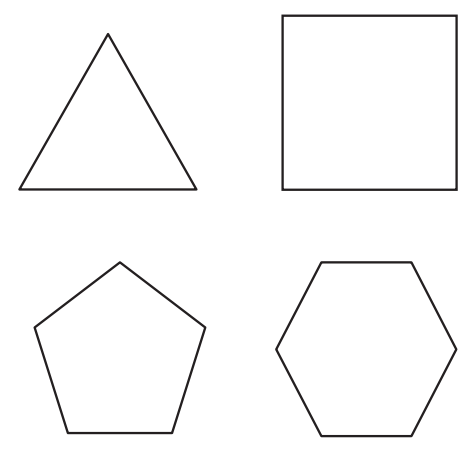

*Tomado de MATLAB para ingenieros de Holly Moore.*

- Pruebe este enunciado usted mismo mediante la creación de un vector llamado `n` desde 3 hasta 6 y calcule la suma de ángulo a partir de la fórmula. Compare lo que sabe de geometría con su respuesta.

- Solicitar al usuario que seleccione la figura trigonométrica entre triángulo, cuadrado, pentágono y exágono. En función de la selección hecha asignar el número de lados y calcular la suma de los ángulos.

**Recomendación:** Para el literal 2 utilizar la función `menu` (consultar la documentación si es necesario).

*Ejercicio modificado de Moore, 2007.*

### Solución

% Inciso 1
n = 3:6

n =      3     4     5     6


sumaAng = (n - 2) .* 180

sumaAng =    180   360   540   720


% Comentarios
% la suma de ángulos internos de un triángulo es: 180°
% la suma de ángulos internos de un cuadrado es: 360°
% la suma de ángulos internos de un pentágono es: 540°
% la suma de ángulos internos de un exágono es: 720°

% Inciso 2
figGeo = menu("Elegir figura geométrica","triángulo","cuadrado","pentágono","exágono");

switch figGeo
    case 1
        n_lados = 3;
        sumAng = (n_lados - 2) * 180;
     case 2
        n_lados = 4;
        sumAng = (n_lados - 2) * 180;
     case 3
        n_lados = 5;
        sumAng = (n_lados - 2) * 180;
     case 4
        n_lados = 6;
        sumAng = (n_lados - 2) * 180;
end

fprintf("la suma de ángulos internos de la figura es: %u°",sumAng);

la suma de ángulos internos de la figura es: 180°

### Ejercicio 2

Solicitar al usuario por teclado un caracter alfanumérico (una letra o un dígito del 0 al 9). Mostrar por pantalla el tipo de caracter ingresado en base a la siguiente clasificación

- vocal

- consonante

- número

**Recomendación:** Agrupar los casos que sean necesarios. Por ejemplo, para las vocales el caso sería `{"a" "e" "i" "o" "u"}`. Consultar la documentación de la función `switch` si es necesario.

### Solución

char_input = input('Ingrese un carácter alfanumérico: ', 's');

switch char_input
    case {'a', 'e', 'i', 'o', 'u'}
        disp('El carácter ingresado es una vocal.');
    case {'b', 'c', 'd', 'f', 'g', 'h', 'j', 'k', 'l', 'm', 'n', 'ñ', 'p', 'q', 'r', 's', 't', 'v', 'w', 'x', 'y', 'z'}
        disp('El carácter ingresado es una consonante.');
    case {'0', '1', '2', '3', '4', '5', '6', '7', '8', '9'}
        disp('El carácter ingresado es un número.');
    otherwise
        disp('El carácter ingresado no es válido.');
end

El carácter ingresado es una vocal.


### Ejercicio 3

En la Universidad de Utah, cada especialización en ingeniería requiere un número diferente de créditos para graduación. Por ejemplo, en 2005, los requisitos para algunos de los departamentos fueron los siguientes:

- Ingeniería civil: 130

- Ingeniería química: 130

- Ingeniería en computación: 122

- Ingeniería eléctrica: 126.5

- Ingeniería mecánica: 129

Solicite al usuario a seleccionar un programa de ingeniería desde un menú (utilizando la función `menu`). Luego, desplegar por pantalla el número mínimo de créditos requeridos para la graduación.

*Ejercicio modificado de Moore, 2007.*

### Solución

programa = menu("Selecciones especialización de ingeniería: ","Ing. civil","Ing. química", ...
    "Ing. en computación","Ing. eléctrica","Ing. mecánica");

switch programa
    case 1
        disp("Número mínimo de créditos requeridos para la graduación: 130");
    case 2
        disp("Número mínimo de créditos requeridos para la graduación: 130");
    case 3
        disp("Número mínimo de créditos requeridos para la graduación: 122");
    case 4
        disp("Número mínimo de créditos requeridos para la graduación: 126.5");
    case 5
        disp("Número mínimo de créditos requeridos para la graduación: 129");
end

Número mínimo de créditos requeridos para la graduación: 126.5
